## **Impulse and step responce**

### Numerical Calculation

In signal analysis, each system can be transformed into a trasfer function. In order to do that two ways can be followed: numerical and analytical. 

Regarding the numercial one, it can be used the `tfestimate` MATLAB. Basically, taking the input and ouput it can develop the transfer function. In the case analysed, the signals can be directly taken from the Simulink enviroment and from them the TF can be evalued. As always, data have to be loaded.

dati = 'DatiSospensione'; %obtain the data from the data file
open(dati)
run(dati)

warning('off','all')

The simualtion considered take as input the chirp signal since we are dealing with frequency-linear-varying signals. The corresponding simulation is the third one:

z0=0; zd0=0; Ts = 100;
V_in = 1/3.6; V_end = 130/3.6;  lambda = 2; h0 = 2/100;
w_in = 2*pi*V_in/lambda;        w_end = 2*pi*V_end/lambda;
f_in=w_in/2/pi;                 f_end=w_end/2/pi;

T_sampling = 1*10^3; %Hz
decimation = 1;

nfile = 'sim_ES01_03';
open(nfile)
sim(nfile)

From the simulation it is possible to load the variables into the MATLAB workspace. Then they can be directly put inside the `tfestimate `command. Note that useless input can be substitued as `[]`. 

The results are showed only up to 22 Hz since these are the two velocities correspoding to 0 and 130 km/h, which are the two road exitation frequencies.

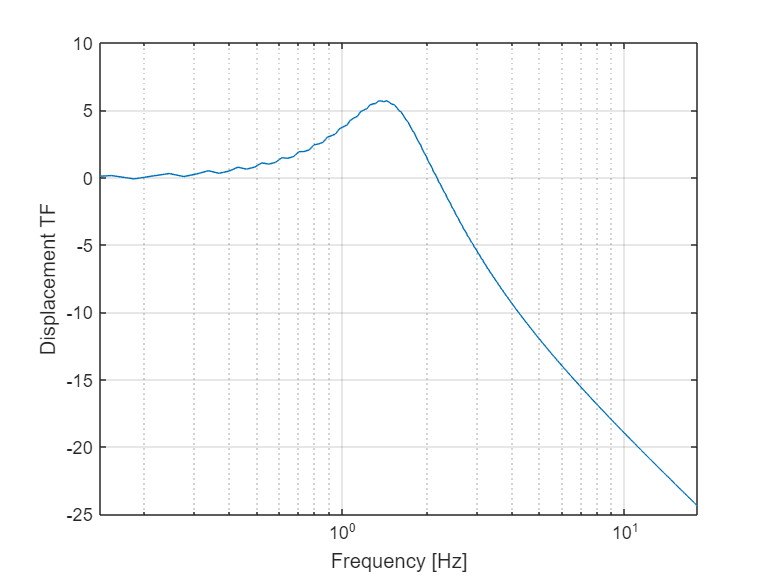

% Displacement
[Tf_z_h,F] = tfestimate(h_tf.data(:,1),z.data(:,1),[],[],[],T_sampling);
% [Txy,F] = tfestimate(x,y,window,noverlap,nfft,Fs)
f = linspace(f_in,f_end,length(Tf_z_h));

figure(3)
% plot(F,abs(Tf_z_h)) 
semilogx(F,20*log10(abs(Tf_z_h)))
grid on
xlabel('Frequency [Hz]')
ylabel('Displacement TF')
xlim([f_in f_end])

The bode diagram of the displacement permit to observe how for higher the frequency less the motion of the mass is following the road. The motion described is an harmonic one where the frequency of the excitation highly influence the system, since the frequency is proportional to the square of the omega, 

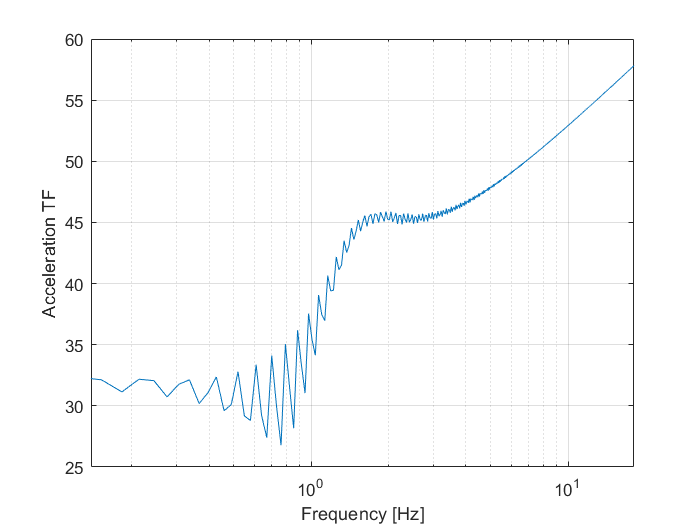

% Acceleration
[Tf_zdd_h,F] = tfestimate(h_tf.data(:,1),zdd.data(:,1),[],[],[],T_sampling);
% [Txy,F] = tfestimate(x,y,window,noverlap,nfft,Fs)
f = linspace(f_in,f_end,length(Tf_zdd_h));

figure(4)
semilogx(F,20*log10(abs(Tf_zdd_h)))
% plot(F,abs(Tf_zdd_h)) 
grid on
xlabel('Frequency [Hz]')
ylabel('Acceleration TF')
xlim([f_in f_end])

Since the transfer funciton is estimated by a signal, here it is possibile to see how the the tendency is correct but with notable distortion. Furthermore, being the damping set as the optimal one, it is possible to see how there is a part of the curve with an horizontal tangent. 

In general, the critical damping is a trade off between damping effect and dissipative terms. Being the displacement evolution the best one for the optimal damping, it means that in our case it is possible to assume an overdamped system, whihc translates into having more heat generation inside the damper. 

### Analytical Calculation

For the sake of studying the dynamic responce of a system, the Bode function of teh system could give important informations. The Bode diagram is basically the "gain" of the output responce respect to the input given. 

It can be directly obtianed by the dynamic equation, performing a Laplace substitution and writing everything in function of the gain wanted. In this example, as before, the two output requested are the acceleration and the displacement.

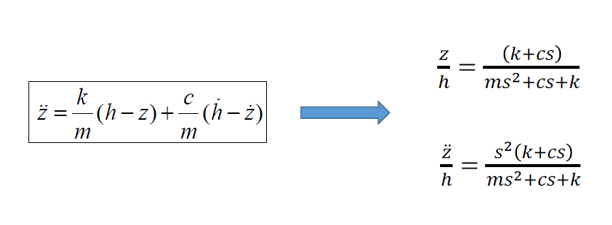

The bode diagram can be easly rìplot thanks to the MATLAB instruments.

dati = 'DatiSospensione'; %obtain the data from the data file
open(dati)
run(dati)

warning('off','all')

- **Displacement TF**

The code is directly provided by the slides. However it is a simple run of a TF function written by hand into the `bode` command.

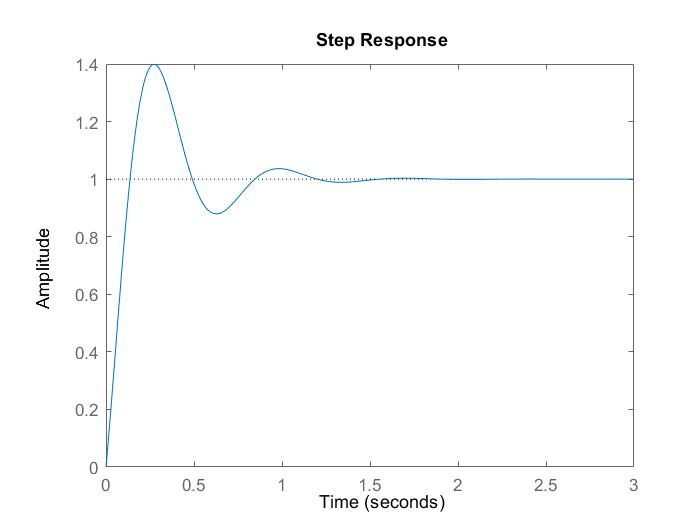

s = tf('s');
G_z_h = (k+c*s)/(m*s^2+c*s+k);
t_vet = 0:0.01:3;
figure(1); hold all; grid on
title('Displacement')
step(G_z_h,t_vet)

First figure show the step responce of the system. The behaviour is the same obtianed from the Simulink model, showing that both procedure are correct.

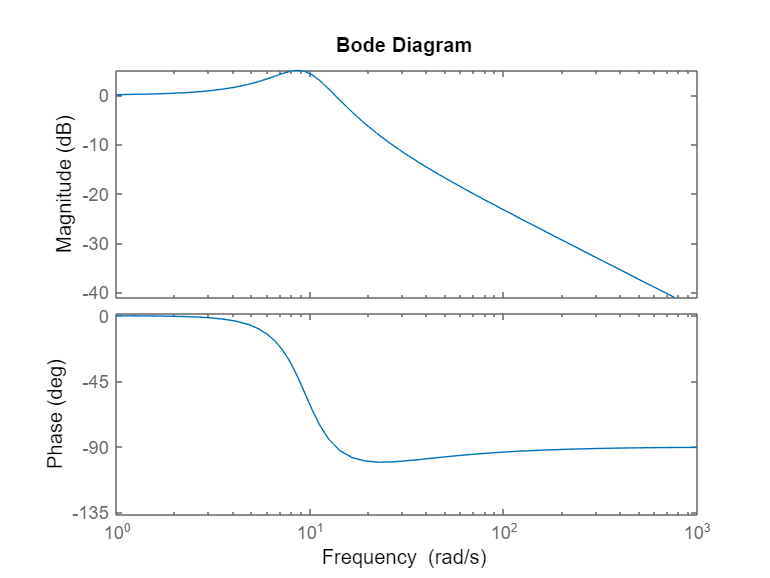

figure(2); hold all
title('Displacement')
bode(G_z_h)

The command `bode` automatically plot both the magnitude and the phase of the system. In the TF of the displacement are present 1 zero and 2 poles, which into the Bode diagram translates into having a +10dB/dec and two -20dB/dec. This is what is seen in the plot, where the zero is in the middle of the first decade ($10^0 < pole <10^1$), one zero is at $10^1$ and the other one is just above $10^1$. The identification of each zero and pole is facilitated thanks to the phase diagra, where each zero and pole correspond to an inflection point.

**NOTE**: There is a direct correspondence between the Bode diagram and the Bode plot. 

They are both system responces to a linear frquency varint inputs. Therefore, they have to have similar magnitude behaviours. 

**Chirp signal:**

% z0=0; zd0=0; Ts = 100;
% V_in = 1/3.6; V_end = 130/3.6; lambda = 2;
% w_in = 2*pi*V_in/lambda;
% w_end = 2*pi*V_end/lambda;
% 
% nfile = 'sim_ES01_03';
% open(nfile)
% sim(nfile)

Overlapping the `bode plot` with the *chirp signal* responce. Please note thet the `bode` command permit to distinguish the magnitude and the phase into two different vectors. However, it saves the two vectors as each value for a certian frequency is equal to an array 1x1. Consequently, `MAG` is a 1x1x1001 vector. For this reason the command `squeeze` is needed, so to convert `MAG` into a normal array.

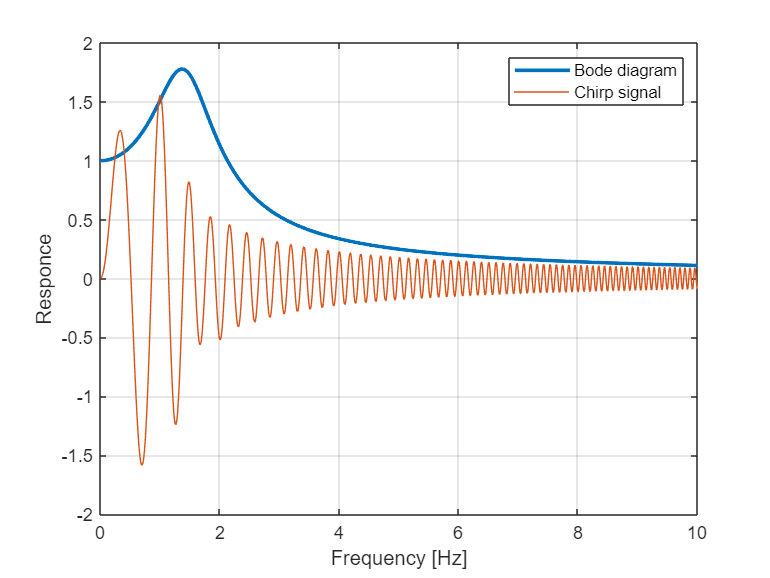

f_vet = 0:0.01:10; %frequency range 0<f<10
w_vet=2*pi*f_vet;
[MAG,~] = bode(G_z_h,w_vet); %~ used to ignore the PHASE vector

figure

% BODE
plot(f_vet,squeeze(MAG),'linewidth',2); %squeeze permit to eliminate 
ylabel('Responce'); xlabel('Frequency [Hz]')
xlim([0 10]) %only plot the frequency up to 10Hz
hold on; grid on

%CHIRP
plot(z(:,1),'linewidth',0.5);
legend('Bode diagram','Chirp signal')

**LTI**:

The last command is the `ltiview`. It is a usefull plot managing system, where each TF declared in the workspace can be plotted and anaylsed. It is usefull when there are several filters, to study the behaviour of each of them. For sake of presentation, its window is now showed, but its functioning is pretty simple.

% ltiview

- **Acceleration TF**

The procedure used for evaluating the transfer function of the dispalcement can be followed to evaluate the transfer function of the acceleration.

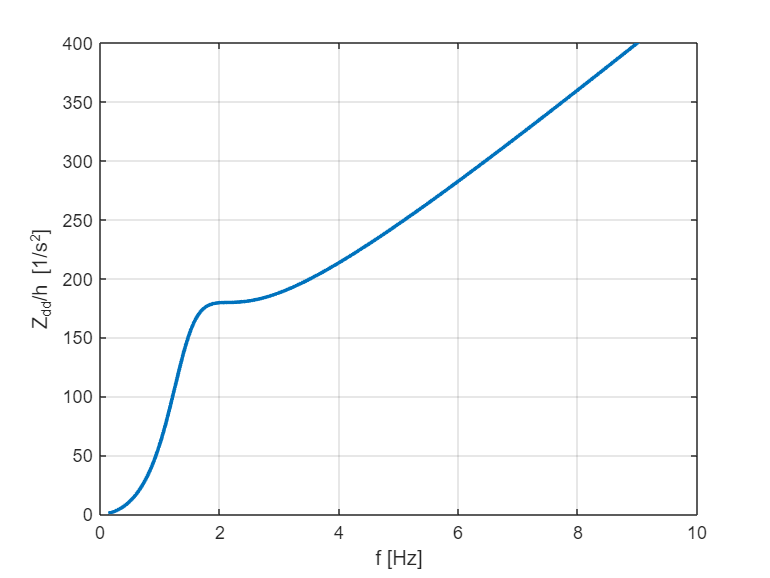

s = tf('s');
G_zdd_h = s^2*(k+c*s)/(m*s^2+c*s+k);

%plot variables
f_vet = f_in:0.01:f_end;
w_vet=2*pi*f_vet;
[MAG,~] = bode(G_zdd_h,w_vet);
figure
plot(f_vet,squeeze(MAG),'linewidth',2);
xlabel('f [Hz]'); ylabel('Z_{dd}/h [1/s^2]')
xlim([0 10]); ylim([0 400]); grid on

Since the formula shows us three zeros and two poles, the overall plot should have 5 inflection points, which is confirmed since the plot has 4 different concavity. 

**Comparing acceleration TF with different damping values**

To compare the behaviour change due to different damping factors, it could be usefull to plot the acceleration TF for different values of *c*. The selected ones are: close to 0, c_opt, 2c_opt, c_cr, c>>>c_cr.

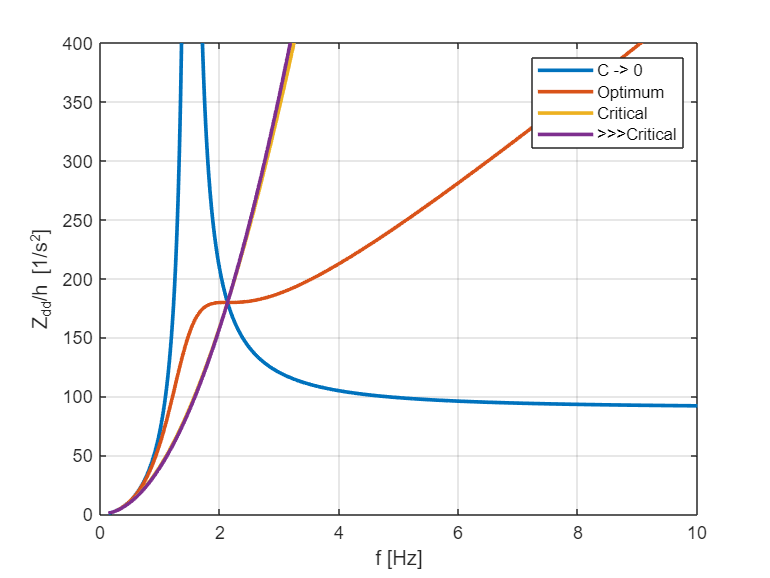

%close to 0 -> 0.01
c = 0.01;
G_zdd_h = s^2*(k+c*s)/(m*s^2+c*s+k);
f_vet = f_in:0.01:f_end;
w_vet=2*pi*f_vet;

figure(10)
[MAG,~] = bode(G_zdd_h,w_vet);
plot(f_vet,squeeze(MAG),'linewidth',2);
% figure settings
xlabel('f [Hz]'); ylabel('Z_{dd}/h [1/s^2]')
xlim([0 10]); ylim([0 400]); grid on; 
hold on

%optimum
c = sqrt(m*k/2);
G_zdd_h = s^2*(k+c*s)/(m*s^2+c*s+k);

figure(10)
[MAG,~] = bode(G_zdd_h,w_vet);
plot(f_vet,squeeze(MAG),'linewidth',2);


%% Critical
c = 8*sqrt(m*k/2);
G_zdd_h = s^2*(k+c*s)/(m*s^2+c*s+k);

figure(10)
[MAG,~] = bode(G_zdd_h,w_vet);
plot(f_vet,squeeze(MAG),'linewidth',2);

hold on

%% Big values
c = 10*8*sqrt(m*k/2);
G_zdd_h = s^2*(k+c*s)/(m*s^2+c*s+k);

figure(10)
[MAG,~] = bode(G_zdd_h,w_vet);
plot(f_vet,squeeze(MAG),'linewidth',2);

legend('C -> 0','Optimum','Critical','>>>Critical')

Let's takes some notes about the results. 

- Firstly with negligible amoutn of damping, the system will tend to have oscillatory behaviour, transalting into an asymptote for a certain frequency. Physically it means that the gain between the input and the output at this frequency is enormous: the system will have great displacmenet even if a small road profile has been imposed.

- The optimum value suggested by the exercise shows the best displacement filtering option. In fact the same value of frequency, the optimum value shows less movements than the critical one.

- The critical damping have as peculiar characteristic the fact that i the bode plot the TF is a simple parabola. 

- For values above the critical one, the system is overdamped, which shows that for higher values of damping teh filtering effects does not change so much. For this reason, since higher values of damping implies great heat dissipation, it is not recommended to use overdamping systems. The critical one is prefered since it provides a performance not so different from the overdamped with less eneeregy dissipation.

**NOTE**: The definition of optimal damping comes from the frequency plot, since it is computed from an analytical esxpression. There is one point point which is always in common with all the damping curves. Taking the derivative from here and putting it equal to zero, permit to compute the curve for which the optimal dampng is obtained. 

**Comparing displacement TF with different damping values**

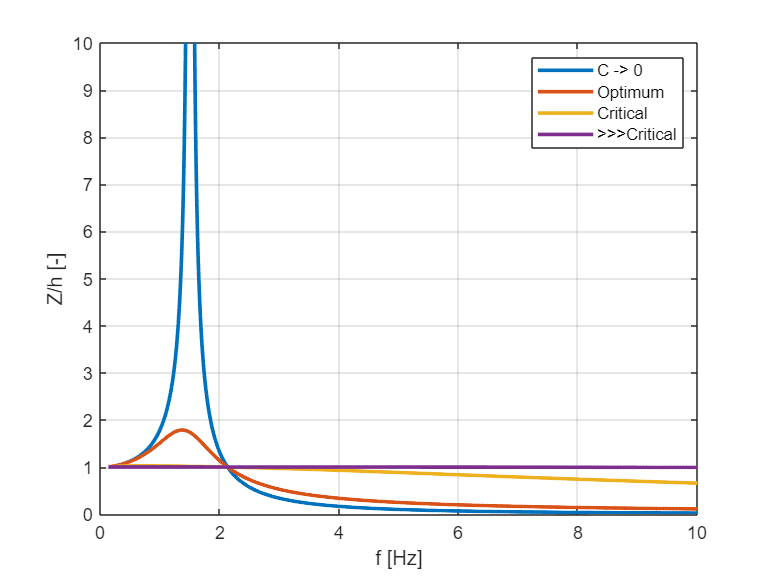

%close to 0 -> 0.01
c = 0.01;
G_z_h = (k+c*s)/(m*s^2+c*s+k);
f_vet = f_in:0.01:f_end;
w_vet=2*pi*f_vet;

figure(11)
[MAG,~] = bode(G_z_h,w_vet);
plot(f_vet,squeeze(MAG),'linewidth',2);
% figure settings
xlabel('f [Hz]'); ylabel('Z/h [-]')
xlim([0 10]); ylim([0 10]); grid on; 
hold on

%optimum
c = sqrt(m*k/2);
G_z_h = (k+c*s)/(m*s^2+c*s+k);

figure(11)
[MAG,~] = bode(G_z_h,w_vet);
plot(f_vet,squeeze(MAG),'linewidth',2);


%% Critical
c = 8*sqrt(m*k/2);
G_z_h = (k+c*s)/(m*s^2+c*s+k);

figure(11)
[MAG,~] = bode(G_z_h,w_vet);
plot(f_vet,squeeze(MAG),'linewidth',2);

hold on

%% Big values
c = 10*8*sqrt(m*k/2);
G_z_h = (k+c*s)/(m*s^2+c*s+k);

figure(11)
[MAG,~] = bode(G_z_h,w_vet);
plot(f_vet,squeeze(MAG),'linewidth',2);

legend('C -> 0','Optimum','Critical','>>>Critical')

Comparing the dispalcement TF for different values of damping it is possible to see that:

- For undamped systems (*c=0*), at the natural frequency the systems is in resonance, oscillating with high amplitude.

- The optimal one suggest a great filtering effect, suggesting that it has a great filtering effect for the displacement

- However, regarding the critical damping it is possible to see how it shows one of the best behaviour of damped, since the curve is nearly constant around 1, which translates into having the *z *equal to the road profile *h*.

- Of course having overdamperd situation this effect is henhanced, since the TF stay equal to 1 even gor higher ranges of frequency.

**CONCLUSION: **The optimal damping shows the best filtering regarding acceleration meanwhile the criticalone (or overdamped in general) shows the best damping effect for displacement.